clear all
close all
clc

d1 = 1;
L1 = 1;
L2 = 1;
L3 = 1;

%a utiliser pour obtenir l'expression litérale du FK
%syms q1 q2 q3 q4 q5;

% angles des liaisons pivots en RAD
Q1 =0 *3.1415/180;
Q2 =90 *3.1415/180;
Q3 =0 *3.1415/180;
Q4 =0 *3.1415/180;
Q5 =0 *3.1415/180;


%calculate the matrixes
T_01 = create_distal_T_ij(0 , 0    , 0  ,0);


T_12 = create_distal_T_ij(0 , pi/2 , d1 ,Q1);
T_23 = create_distal_T_ij(L1, 0    , 0  ,Q2);
T_34 = create_distal_T_ij(L2, 0    , 0  ,Q3);
T_45 = create_distal_T_ij(0 , -pi/2, 0  ,Q4);
T_56 = create_distal_T_ij(0 , 0    , L3 ,Q5);

T_13 = T_12 *T_23;
T_14 = T_12 *T_23  *T_34;
T_15 = T_12 *T_23  *T_34 *T_45;
T_16 = T_12 *T_23  *T_34 *T_45 *T_56;

%a utiliser pour obtenir l'expression litérale du FK
%a=simplify(T_16(3,4));

%les positions de chaque liaison
x1=0;
y1=0;
z1=0;

x2=T_12(1,4);
y2=T_12(2,4);
z2=T_12(3,4);

x3=T_13(1,4);
y3=T_13(2,4);
z3=T_13(3,4);

x4=T_14(1,4);
y4=T_14(2,4);
z4=T_14(3,4);

x5=T_15(1,4);
y5=T_15(2,4);
z5=T_15(3,4);

x6=T_16(1,4);
y6=T_16(2,4);
z6=T_16(3,4);

%vecteurs avec toutes les positions des joints
xx=[x1;x2;x3;x4;x5;x6]

xx =          0
         0
    0.0000
    0.0001
    0.0001
   -0.9999


yy=[y1;y2;y3;y4;y5;y6]

yy = 	1.0e+-15 *

         0
         0
    0.0612
    0.1225
    0.1225
    0.0612


zz=[z1;z2;z3;z4;z5;z6]

zz =          0
    1.0000
    2.0000
    3.0000
    3.0000
    3.0000


## **Plotting**


figure (1)
set(1,'position')

  0×0 empty cell array



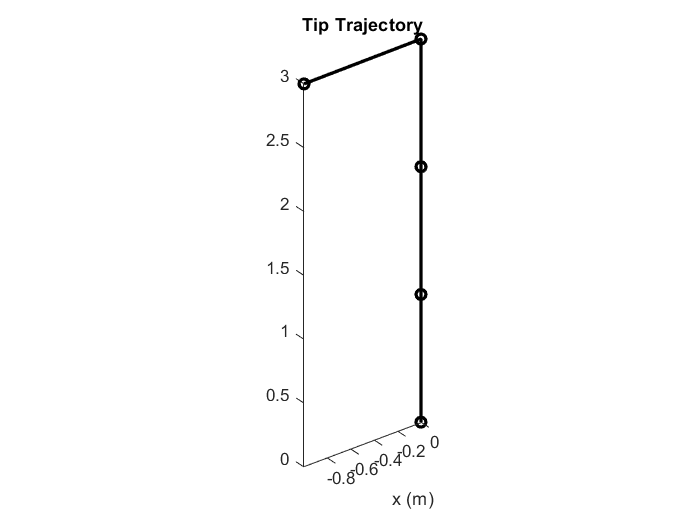


plot3(xx,yy,zz,'ko-','Linewidth',2)  % plot the  position of the robot
axis equal
hold on
title('Tip Trajectory') ; xlabel('x (m)') ; ylabel('y (m)') ;
hold off


%en 2D mais c'est nul
figure (2) 
set(2,'position')

  0×0 empty cell array



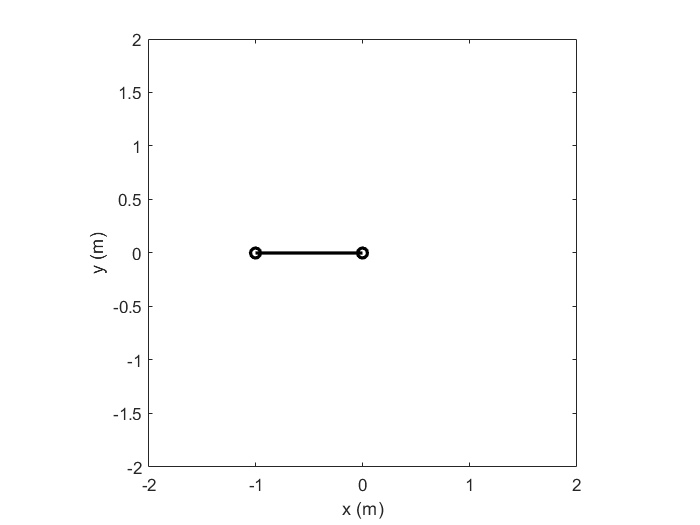


plot(xx,yy,'ko-','Linewidth',2)
axis equal
hold on

xlabel('x (m)') ; ylabel('y (m)') ;
axis([-2 2 -2 2])
hold off